clear; close all; clc; clf; 
%project code 
%inputs and constants 
a_0 = 0.03; % burn rate paraemter a 
n = 0.35; % burn rate partemeter n 
sigma_p = 0.001; % burn rate temperature sensitivity 
gamma_p = 1.25; % ratio of the specific heats of the propelent products 
cstar = 5210; % c* 
rho_p = 0.065; % density of the unburned propelent 
mw_air = 28.97; % molecular weight of the air in lb/lb-mol 
gamma_air = 1.4; % ratio of the specific heats of the air 
A_rocket = pi*(6.19/24)^2; % area of the rocket in ft 
R_u = 1545.3; % universal gas constant in english units 
ge = 32.2; % gravatational acceleration in ft/s^2 
T_b0 = 70; % refrence burn sensitivity temperature in F 
m_pl = 40; % mass of the payload in lbm 
w_step = 0.01; % web step distance for all but the last websteps in in 

%Design inputs 
r_i = 1; % inner radius of the grain in in; 
r_o = 2.375; % outer radius of the grain in in 
l_0 = 8; % length of one grain in in 
Ngrain = 4; % number of grains 
eta_0 = 4; % area ratio of the throught to the exit 
A_t0 = 1; % starting throught area in in^2 
m_bal = 1; % balast mass in lbm T_b = 100; % burn sensitivity temperature in F 
T_b = 70; % propelent temperature

% some starting calculations 
if (l_0/2) < (r_o - r_i) 
    wmax = l_0/2; 
else 
    wmax = r_o - r_i; 
end 
w = [0:w_step:wmax wmax]; % web distance at each step in the internal ballistics 
c = length(w);
le = 1000;
w = [w zeros(1,le-c)];
% Calculate the initial burn area based on the grain dimensions 
A_b = Ngrain * pi .* ((r_o^2 - (r_i + w).^2).*2 + ((r_i + w).*2).*(l_0 - 2.* w)); 
% exit area 
A_e0 = eta_0*A_t0; 
m_case = Ngrain * (l_0 + 0.125) * 0.25;

chamber_pressure = zeros(le,1);
burn_rate = zeros(le,1);
time = zeros(le,1);
propelent_mass = pi.*(r_o^2 - (r_i+w).^2).* rho_p .* (l_0 - 2.*w) .* Ngrain;
propelent_mass = [propelent_mass zeros(1,le-c)];
rocket_mass = zeros(le,1);
area_ratio = zeros(le,1); area_ratio(1) = eta_0;
throght_area = zeros(le,1); throght_area(1) = A_e0/area_ratio(1);
throght_diameter = zeros(le,1); throght_diameter(1) = sqrt(throght_area(1)*4/pi);
pcpa = zeros(le,1);
thrust_coeff = zeros(le,1);
thrust = zeros(le,1);
impulse = zeros(le,1);
coefficient_of_drag = zeros(le,1);
drag_over_mass = zeros(le,1);
acceleration = zeros(le,1); acceleration(1) = -ge;
velocity = zeros(le,1);
altitude = zeros(le,1);
speed_of_sound = zeros(le,1);
mach_num = zeros(le,1);


for i = 1:(le-1) 
    
    chamber_pressure(i) = (a_0 * exp(sigma_p*(T_b-T_b0)) * rho_p * A_b(i) * cstar/(ge * throght_area(i)))^(1/(1-n)); 

    if i > c
        chamber_pressure(i) = 0;
    end

    burn_rate(i) = a_0 * exp(sigma_p*(T_b-T_b0)) * chamber_pressure(i)^n;

    if i < c
        time(i+1) = time(i) + (w(i+1) - w(i))/burn_rate(i);
    elseif i >= c
        time(i+1) = time(i) + 0.1;
    end

    %thrust section
    throght_diameter(i+1) = throght_diameter(i) + 0.000087 * (time(i+1)-time(i)) * chamber_pressure(i);

    throght_area(i+1) = throght_diameter(i+1)^2 * pi/4;

    area_ratio(i) = A_e0/throght_area(i);

    pcpa(i) = chamber_pressure(i)/press(altitude(i));

    thrust_coeff(i) = thrust_coefficient(gamma_p,area_ratio(i),pcpa(i));

    thrust(i) = thrust_coeff(i) * chamber_pressure(i) * throght_area(i);

    if i > c
        thrust(i) = 0;
        propelent_mass(i) = 0;
    end
    rocket_mass(i) = propelent_mass(i) + m_pl + m_bal + m_case;

    speed_of_sound(i) = sqrt( gamma_air * R_u/mw_air * ge * temp(altitude(i)));

    mach_num(i) = velocity(i)/speed_of_sound(i);

    coefficient_of_drag(i) = drag_coeff(mach_num(i));

    drag_over_mass(i) = 1/2 * density(altitude(i)) * abs(velocity(i)) * velocity(i) * A_rocket * coefficient_of_drag(i)/rocket_mass(i);
    

    acceleration(i) = thrust(i)/rocket_mass(i) * ge - ge - drag_over_mass(i);

    velocity(i+1) = velocity(i) + acceleration(i) * (time(i+1)-time(i));

    altitude(i+1) = altitude(i) + 1/2 * (velocity(i+1) + velocity(i)) * (time(i+1)-time(i));
    
    

end

for i = 1:le-1
    impulse(i+1) = (thrust(i+1) + thrust(i)) * 0.5 * (time(i+1) - time(i));
    impulse(c+1) = 0;
end

isp = sum(impulse(1:(c)))/propelent_mass(1)

isp =      2.419955088324720e+02


max(thrust)

ans =      1.885651217930626e+03




max(acceleration)

ans =      7.990182293268301e+02


acceleration(c)

ans =      5.408039949353806e+02


max(velocity)

ans =      3.178451519404151e+03


velocity(c)

ans =      3.124371119910613e+03


max(altitude)

ans =      5.810406601719734e+04


altitude(c)

ans =      7.062983669372123e+03


time(c)

ans =    4.325616779480742


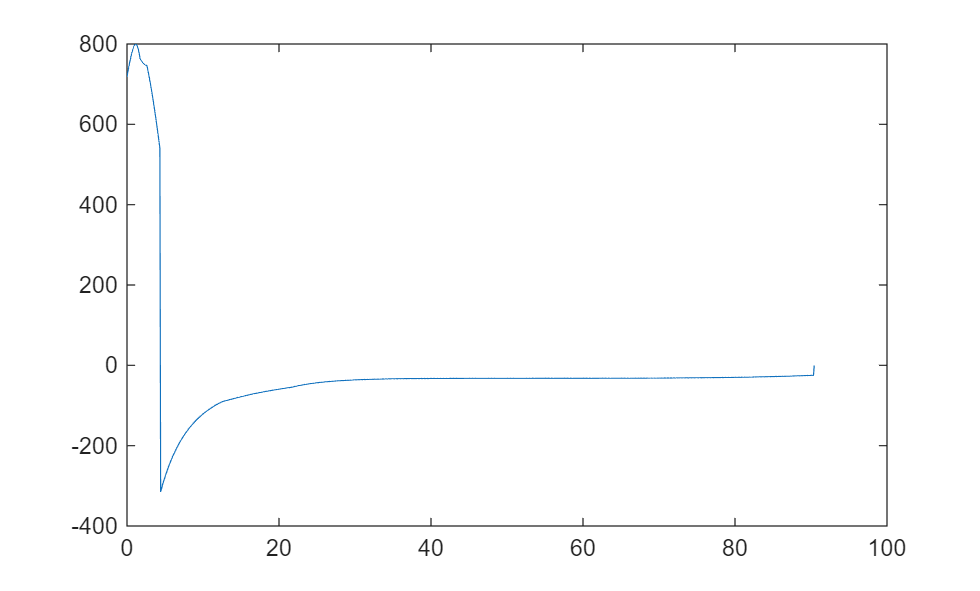

plot(time,acceleration)

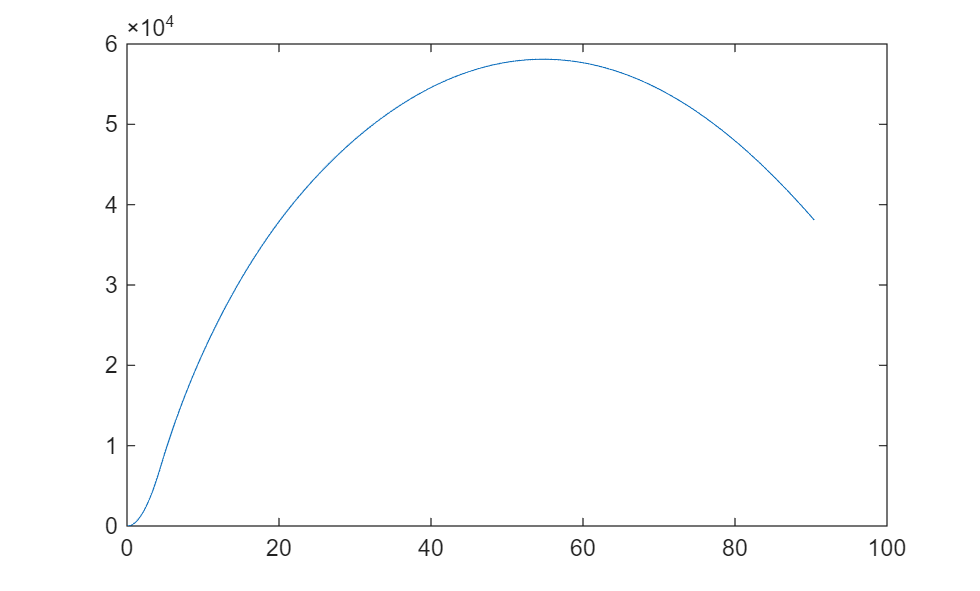

plot(time,altitude)


function [ta] = temp(alt)
    if alt < 32809
        ta  = -0.0036*alt+518;
    else 
        ta = 399;
    end
end

function [pa] = press(alt)
    if alt < 83000
        pa = -4.272981E-14*alt^3 + 0.000000008060081*alt^2 -0.0005482655*alt + 14.69241;
    else
        pa = 0;
    end
end

function [rho] = density(alt)

    if alt < 82000
        rho = 0.00000000001255*alt^2 - 0.0000019453*alt + 0.07579;
    else
        rho = 0;
    end
end

function [cf] = thrust_coefficient(gamma, areaRatio, pcpa)
    [~,mach] = machNumbers(areaRatio,gamma);
    papc = 1/pcpa;
    pepc = (1+ (gamma-1)/2 * mach^2 )^(-gamma/(gamma-1));
    one = (2*gamma^2)/(gamma-1);
    two = (2/(gamma+1))^((gamma+1)/(gamma-1));
    three = (1 - pepc^((gamma-1)/gamma));
    four = sqrt(one*two*three);
    five = (pepc-papc)*areaRatio;
    cf = four + five;
end

function [cf] = thrust_coefficient_special(gamma,areaRatio)
% Calculate the thrust coefficient using the given parameters
    [~,mach] = machNumbers(areaRatio,gamma);
    pcpe = (1+ (gamma-1)/2*mach^2)^(gamma/(gamma-1));
    pepc = pcpe^(-1);
    papc = pepc;
    cf = (2*gamma^2/(gamma-1)*(2/(gamma+1))^((gamma+1)/(gamma-1))*(1-pepc^((gamma-1)/gamma)))^0.5 + (pepc - papc)*areaRatio;
end

function [cd] = drag_coeff(mach)

    if mach < 0.6
        cd = 0.15;
    elseif mach < 1.2
        cd = -0.12+0.45*mach;
    elseif mach < 1.8
        cd = 0.76-0.283*mach;
    elseif mach < 4
        cd = 0.311-0.034*mach;
    else
        cd = 0.175;
    end
end

function [M_sub, M_super] = machNumbers(areaRatio, gamma)
% machNumbers - Computes the subsonic and supersonic Mach numbers
% corresponding to a given area ratio A/A*

    f = @(M) (1./M) .* ( (2/(gamma+1)) .* (1 + (gamma-1)/2 .* M.^2) ) ...
        .^((gamma+1)/(2*(gamma-1))) - areaRatio;
    try
        M_sub = fzero(f, [1e-6, 0.999]); 
    catch
        M_sub = NaN; 
    end
    try
        M_super = fzero(f, [1.0001, 50]); 
    catch
        M_super = NaN;
    end
end